# YOUR TITLE HERE

*Authors:* Anjum Khalifa

## Generative AI (genAI) Usage Statement

Write a short statement about how you used genAI on this assignment. *Note*: If you don't write anything, we'll assume you used genAI to write the whole thing!!!

I (Anjum Khalifa) did not use GenAI while completing this assignment.

## 1. Modeling Question

How fast do a group of countries need to close its borders to stop the spread of a disease, after transmission has been identified, in order to effectively reduce the rate of spread of disease?

When an epidemic is identified, countries closing borders and prohibiting international travel is typically used as a preventative measure, to reduce the likelihood of a virus managing to escape containment in one country and become a global pandemic. This has been studied and modeled extensively with COVID-19, determining how effective border closures were on containing the virus and what could have happened with open borders. However, most of these studies focus on the presence of the border, and not on the speed at which it is established. 

We were curious about how a disease might spread across countries if those countries close their borders immediately after a disease is identified within its borders, or if they wait to establish a border until the disease has spread further. Unfortunately, we were uncertain of how this might be modeled, and what factors (ocean vs. land border, country size, prior policies, social connection within countries, etc.) would be necessary in our model. To answer this question, we conducted background research on this topic and synthesized our findings.

Specificity: Our question is a specific question. We are not seeking to understand the general behavior of restricted travel on a global pandemic, but instead exactly how fast one must be implemented to reduce the spread of such a pandemic. 

Action: Our question is a rhetorical question. While our results may indicate that policy must be skewed one way or another to control the international spread of a virus, we are not taking direct action based on our results, and instead seeking to inform decisions others may make in the future.

## 2. Literature Search

*(Identify 3 or more scholarly articles that are relevant to your modeling question. Analyze these references using the synthesis matrix approach. Report your synthesis matrix in a readable format: Include a link to a Google Sheet if it does not fit in the report.)*

*(You will likely need to write 2-3 paragraphs for this section.)*

*A: we learned X from article 1, Y from article 2, and Z from article 3*

*B: but we didn't find a direct answer to our modeling question*

*T: so we went on to build a model*

Synthesis matrix: [*https://docs.google.com/spreadsheets/d/1xcnw-RDwNBq6Txi01jzwjk31aJafs17oE7vinwlC54A/edit?usp=sharing*](https://docs.google.com/spreadsheets/d/1xcnw-RDwNBq6Txi01jzwjk31aJafs17oE7vinwlC54A/edit?usp=sharing) 

## 3. Natural World

*(Describe the natural world using your 3 or more scholarly articles. Use an inline citation every time you refer to a fact from one of the scholarly articles. Everything you describe should be relevant to your modeling question. This section should connect to your tenchi diagram; we recommend putting the diagram directly between sections 3 and 4 since it serves as a transition between the two.)*

*(You will likely need to write 2-3 paragraphs for this section.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: here's a few things that are important in the natural world*

*B: but there are some things we assumed are not relevant to our modeling question*

*T: so, we left those things outside the system boundary (they are not modeled)*

## 4. Model: Representation & Assumptions

*(Describe how your model represents the natural world. Use a tenchi diagram to illustrate what parts of the natural world are inside the system boundary. In the same tenchi diagram, provide a visual of your model. Describe in words how your model represents the chosen system. Describe in words what assumptions you have made. Cite your references when appropriate.)*

*(You will likely need to write 5-7 code & text regions for this section. You should have images and equations to describe your model, and then implement your model in code.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: this part of the natural world is important for our question*

*B: but we can't include that directly because of X reason*

*T: so here is the way we represented it / what we assumed to simplify*

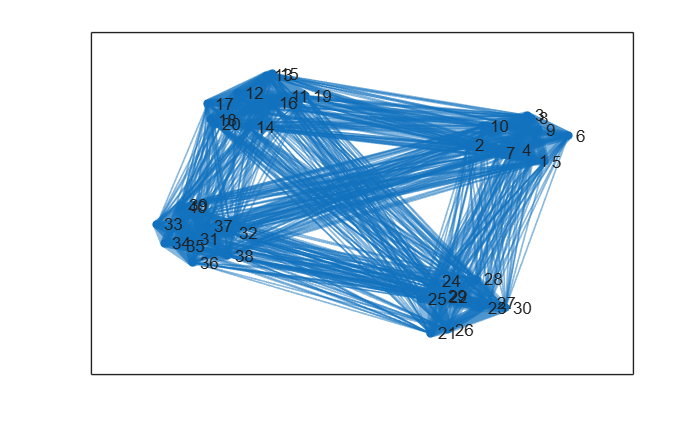

% creating "leaky" pods to represent countries
country_size = 10;
num_countries = 4;

M_countries = ones(country_size * num_countries);
M_country = (ones(country_size) - eye(country_size)) * 5;

for i = 0:(num_countries - 1)
    M_countries(i * country_size + 1:(i + 1) * country_size, i * country_size + 1:(i + 1) * country_size) = M_country;
end
graph_countries = graph(M_countries);

% stole some of these lines from w4p3 - "clumps" pods together 
% and makes lines thicker based off weights
figure;
LWidths = 5 * graph_countries.Edges.Weight / max(graph_countries.Edges.Weight);
h = plot(graph_countries, 'LineWidth', LWidths);
layout(h, 'force', 'WeightEffect', 'inverse')

## 5. Verification & Validation

*(Select appropriate verification facts, and implement them as assert statements. In Projects 2 and 3, carry out model validation.)*

*(You will likely need to write 2-3 code sections for this section, and use words to describe your argument for verification and validation.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: here is a fact that should be true about the model*

*B: but it is not immediately obvious this is true, because X*

*T: so we carried out this test to show that it is true*

## 6. Claims & Limitations

*(Run simulations using your model, and make claims about the natural world based on those results. Connect each assumption to a limitation about what you *cannot* conclude based on your model.)*

*(You will likely need to write 2-3 code sections for this section [generating results with your model], and 2-3 paragraphs making claims using your results, and discussing the limitations.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: remember this assumption from Section 4*

*B: but [our model still captures X important trend OR our question is about Y specifically OR our results are still informative because of Z]*

*T: so, we can conclude X, keeping in mind Y caveats*

## 7. Conclusion

*(Restate your modeling question, and refer to the claims from Section 6. Use your claims to directly answer your modeling question.)*

*(You will likely need just 1 paragraph for this section.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: this part of the natural world is important, and X is already known*

*B: but Y is not yet known, so we built a model to answer the question ...*

*T: so, given [particular result from Section 6], we conclude Z*

## 8. Future Work

*(Based on your limitations from Section 6, state 2 or more ideas of future work for other modelers to attempt.)*

*(You will likely need 2-3 paragraphs for this section.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: our model assumed X*

*B: but the natural world is actually like Y*

*T: so there are open questions, such as Z*

## References

*(List all references alphabetically by last name. Use the following format: Last name 1, Last name 2, ... (Year) "Title of Reference")*